% clear;
data = load('resultadosCSV_5mhz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*5e6)

T_buscado =      1.000000000000000e-07


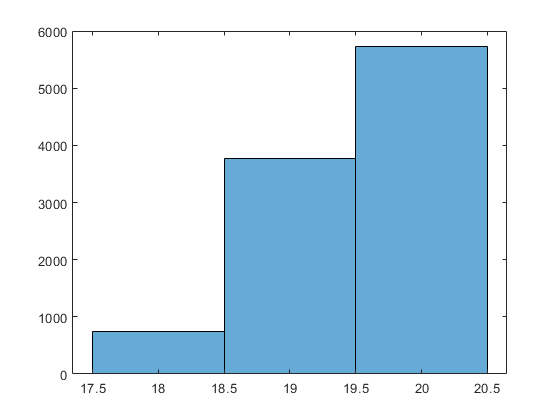

% t_fino = (start)*tau_start - (stop)*tau_stop;
t_fino = (start-stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse);

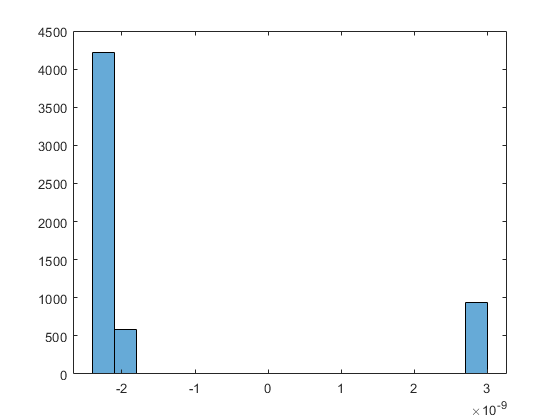


indices_20 = find(coarse==20);
indices_21 = find(coarse==21);

clf;
coarse_20 = coarse(indices_20);
fino_20 = t_fino(indices_20);
histogram(fino_20);

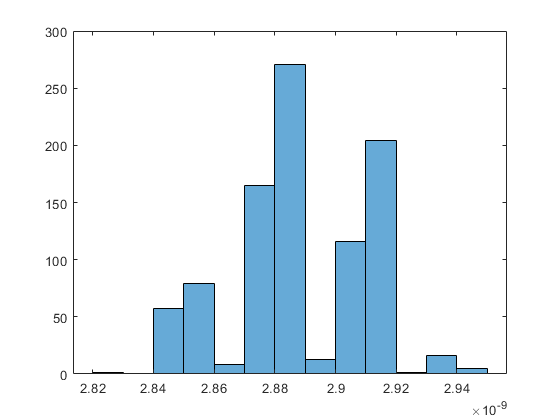

fino_20_malos = fino_20(fino_20<-3e-9);
coarse_20_malos = coarse_20(fino_20<-3e-9);
fino_20_buenos = fino_20(fino_20>0);
coarse_20_buenos = coarse_20(fino_20>0);
histogram([fino_20_buenos; fino_20_malos+T])

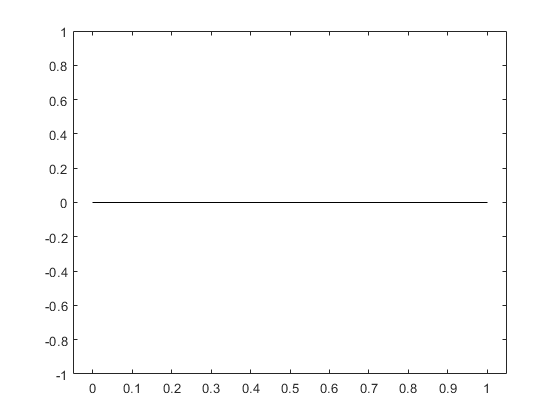


%%fino 21
%%Tenemos que restar un clock!!
fino_21 = t_fino(indices_21);
coarse_21 = coarse(indices_21);
histogram(fino_21)

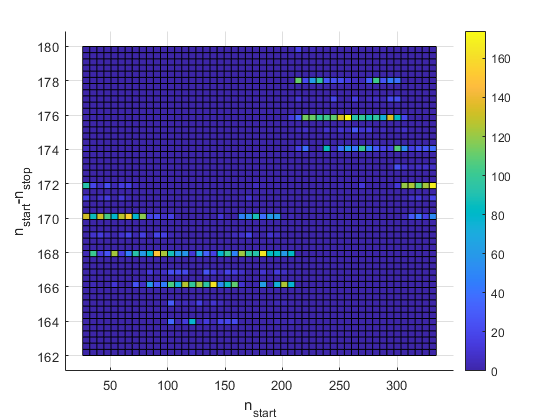

st = start-stop;
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
% std(st_positivo)
hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_5M.eps');

clf;
y = [fino_20_buenos; fino_20_malos+T; fino_21];
presicion = std(y)

presicion =      2.240007493991628e-11


media     = mean(y)

media =      2.889343910256414e-09


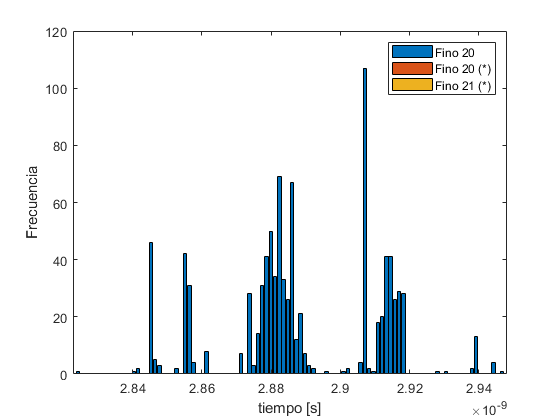

coarse_correcto = 20;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_20_buenos, fino_20_malos+T, fino_21};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end
% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({'Fino 20', 'Fino 20 (*)', 'Fino 21 (*)'});
exportgraphics(gcf,'histograma_5M.eps');


format long
T_buscado

T_buscado =      1.000000000000000e-07


Tiempo_final = 20*T + media

Tiempo_final =      1.028893439102564e-07


error = Tiempo_final - T_buscado

error =      2.889343910256420e-09


clf;

% Data vectors
data = {coarse_20_buenos, coarse_20_malos, coarse_21};

% Number of bins
N = 8;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = 19.5:0.25:21.5

commonEdges =   19.500000000000000  19.750000000000000  20.000000000000000  20.250000000000000  20.500000000000000  20.750000000000000  21.000000000000000  21.250000000000000  21.500000000000000



% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({'Grueso 20', 'Grueso 20 (*)', 'Grueso 21 (*)'});
exportgraphics(gcf,'histograma_coarse_5M.eps');